# **FSIM (Functional SIMulator)**

**per ****f-HDGM**** e ****fp-HDGM**

Parametri da impostare:

- $\rho \ [1\times1]$;

- $\mathbf{c}_{\epsilon} \ [p_{\epsilon}\times 1]$;

- 
$$\mathbf{C}_{\beta} \ [b\times p_{\beta}]$$


- $\Sigma_0 \ [n\cdot p_z\times n\cdot p_z]$;

- $\mathbf{\mu}_0 \ [n\cdot p_z\times 1]$;

- $\mathbf{G} \ [p_z\times p_z]$;

- 
$$\mathbf{V} \ [p_z\times p_z]$$


- $\mathbf{\theta} \ [p_z\times 1]$;

- $n$, $q$, $b$ e $T$

clear all %#ok<CLALL> 
clc
rng('default')

#### **Scelta dei punti**

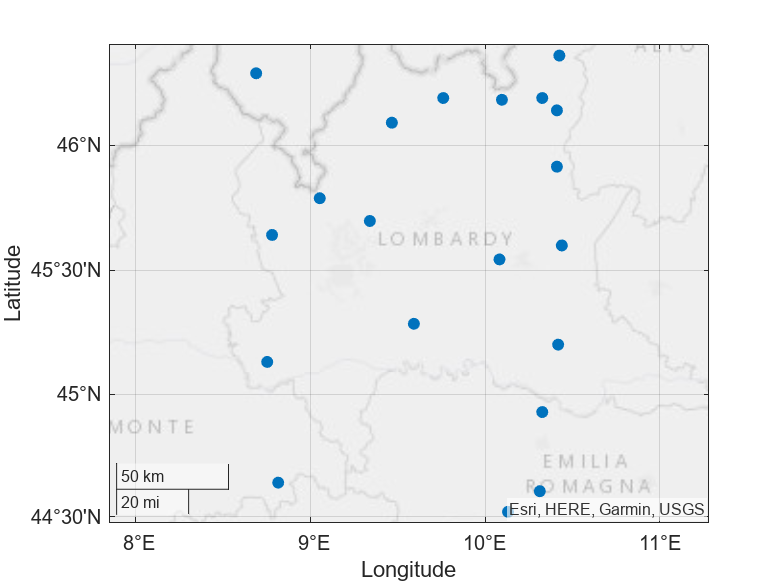

n = 20;
points = FSIM.get_points(n);
geoscatter(points, "Latitude", "Longitude", "filled")

#### Impostazione dei parametri

rng('default')

q = 24;
T = 365;
params.rho = 10;
n_basis.p_eps = 5;
n_basis.p_beta = 7;
n_basis.p_z = 7;

b = 2;
X = cell(T, 1);
for t=1:T
    X_t = ones(q*n, 2);
    for i=2:b
        X_t(:, 2) = randi(100, q*n, 1);
    end
    X{t} = X_t;
end

obj = FSIM(points, q, T, "NumBasis", n_basis, "Parameters", params, "XData", X);

FSIM (Functional SIMulator)
 
Authors: 
- Lorenzo LEONI
- Nicola ZAMBELLI
 
Dimensions: 
- n, q, b and T: [20 24 2 365]
- p_eps, p_beta and p_z: [5 7 7]
 
Parameters set: 
- rho: 10
- c_eps: [21   -0.0664489    -0.193816      1.22426    -0.304687]
- c_beta_1: [46  49  56  59  12  38  65]
- c_beta_2: [25  33  64  16  56  26  82]
- diag_G: [0.12841     0.49478     0.44527     0.10506     0.76462      0.6938     0.73535]
- diag_V: [8   6   1   6   1   1  10]
- theta: [9  9  9  9  9  9  9]


#### Avvio della/e simulazione/i

obj = obj.run(10);

Running simulation/s: 
- sim. 1 of 10 done.
- sim. 2 of 10 done.
- sim. 3 of 10 done.
- sim. 4 of 10 done.
- sim. 5 of 10 done.
- sim. 6 of 10 done.
- sim. 7 of 10 done.
- sim. 8 of 10 done.
- sim. 9 of 10 done.
- sim. 10 of 10 done.


**NB**: si ricorda che le osservazioni $Y_{sim}$ sono impilate prima per $q$, poi per $n$ (fissato $q$, viene espresso il valore di $y$ assunto presso le diverse $n$ stazioni).

#### Validazione dei modelli spazio-temporali

data = obj.preprocess_data;

Running data pre-processing: 
- dataset 1 of 10 done.
- dataset 2 of 10 done.
- dataset 3 of 10 done.
- dataset 4 of 10 done.
- dataset 5 of 10 done.
- dataset 6 of 10 done.
- dataset 7 of 10 done.
- dataset 8 of 10 done.
- dataset 9 of 10 done.
- dataset 10 of 10 done.
